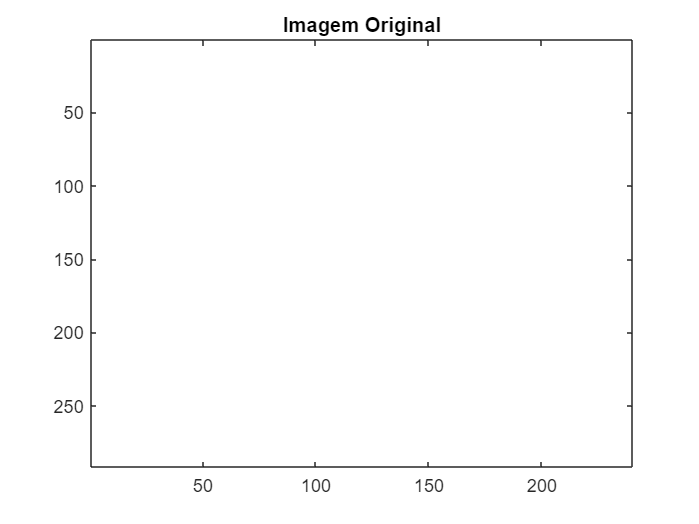

clear
I = imread("pout.tif");

[M, N] = size(I);

L = 256;

I_hist = zeros(L, 1);

for i = 1:M
    for j = 1:N
        I_hist(I(i,j)) = I_hist(I(i,j)) + 1;
    end
end

CFD = zeros(L, 1);

CFD(1) = I_hist(1);

for i = 2:L
    CFD(i) = CFD(i-1) + I_hist(i);
end

I_Eq = size(I);

for i = 1:M
    for j = 1:N
        v = I(i,j);

        I_Eq(i,j) = floor(((CFD(v) - CFD(1)) ./ ((M .* N) - CFD(1))) .* (L - 1));
    end
end

colormap('gray');
imagesc(I); title("Imagem Original")

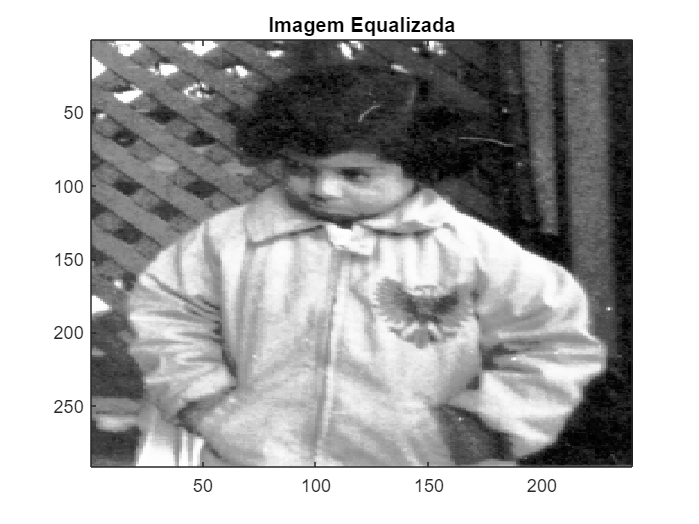

imagesc(I_Eq); title("Imagem Equalizada")